%% 方法一：梯度下降法
x = load('ex3x.dat');
y = load('ex3y.dat');

x = [ones(size(x,1),1) x];
meanx = mean(x);%求均值
sigmax = std(x);%求标准偏差
x(:,2) = (x(:,2)-meanx(2))./sigmax(2);
x(:,3) = (x(:,3)-meanx(3))./sigmax(3);

figure
itera_num = 100; %尝试的迭代次数
sample_num = size(x,1); %训练样本的次数
alpha = [0.01, 0.03, 0.1, 0.3, 1, 1.3];%因为差不多是选取每个3倍的学习率来测试，所以直接枚举出来
plotstyle = {'b', 'r', 'g', 'k', 'b--', 'r--'};

theta_grad_descent = zeros(size(x(1,:)));
for alpha_i = 1:length(alpha) %尝试看哪个学习速率最好
    theta = zeros(size(x,2),1); %theta的初始值赋值为0
    Jtheta = zeros(itera_num, 1);
    for i = 1:itera_num %计算出某个学习速率alpha下迭代itera_num次数后的参数       
        Jtheta(i) = (1/(2*sample_num)).*(x*theta-y)'*(x*theta-y);%Jtheta是个行向量
        grad = (1/sample_num).*x'*(x*theta-y);
        theta = theta - alpha(alpha_i).*grad;
    end
    plot(0:49, Jtheta(1:50),char(plotstyle(alpha_i)),'LineWidth', 2)%此处一定要通过char函数来转换
    hold on
    
    if(1 == alpha(alpha_i)) %通过实验发现alpha为1时效果最好，则此时的迭代后的theta值为所求的值
        theta_grad_descent = theta
    end
end

theta_grad_descent =    1.0e+05 *

    3.4041
    1.1063
   -0.0665


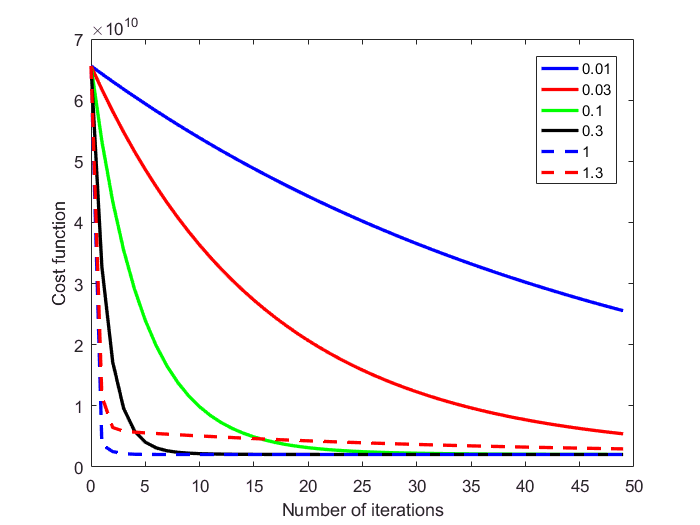

legend('0.01','0.03','0.1','0.3','1','1.3');
xlabel('Number of iterations')
ylabel('Cost function')


%下面是预测公式
price_grad_descend = theta_grad_descent'*[1 (1650-meanx(2))/sigmax(2) (3-meanx(3)/sigmax(3))]'

price_grad_descend = 2.9935e+05

                                     
                                     
%%方法二：normal equations
x = load('ex3x.dat');
y = load('ex3y.dat');
x = [ones(size(x,1),1) x];

theta_norequ = inv((x'*x))*x'*y

theta_norequ =    1.0e+04 *

    8.9598
    0.0139
   -0.8738


price_norequ = theta_norequ'*[1 1650 3]'

price_norequ = 2.9308e+05